# **LPV-MPC: Taylor Extrapolation (Recursive) Approach**

This interactive script demonstrates the Recursive Extrapolation approach for estimating the LPV scheduling parameters using a Two Tank system. 

The nonlinear dynamics are governed by Torricelli's law. We embed the nonlinearities inside bounded scheduling parameters by extracting $\rho_1 =\frac{1}{\sqrt{h_1 }}$ and $\rho_2 =\frac{1}{\sqrt{h_2 }}$.

This method is based on a first-order Taylor expansion. It extracts the base values from the shifted optimal trajectory of the previous time step and corrects them using the analytical Jacobian. To prevent numerical divergence, it enforces strict clipping between physical limits.

## Initialization

First, we build the base CHRONOS MPC structure, initializing the system with the dynamic matrices "frozen" at the starting condition.

% Tank area and gravity value
Ab = 1; g = 9.81; h1 = 0.45; h2 = 0.45; Ts = 0.01;
N = 10;
mpc = init_mpc(N);

% LTI system frozen at current state vector
A = [-sqrt(2*g)*sqrt(h1)/(Ab*h1) 0; sqrt(2*g)*sqrt(h1)/(Ab*h1) -sqrt(2*g)*sqrt(h2)/(Ab*h2)];
B = [1/Ab; 0];
mpc = init_mpc_dynamics(mpc,eye(2)+Ts*A,Ts*B,0);
mpc = init_mpc_output(mpc,[0 1],[],[]);

% Constraints and Costs
mpc = init_mpc_state_cnstr(mpc,0.01*ones(mpc.nx,1), 1*ones(mpc.nx,1));
mpc = init_mpc_control_cnstr(mpc, 0*ones(mpc.nu,1),10*ones(mpc.nu,1));
mpc = init_mpc_control_rate_cnstr(mpc, -0.1*ones(mpc.nu,1), 0.1*ones(mpc.nu,1));
mpc = init_mpc_ter_ingredients_dlqr(mpc, diag([30 30]), 1, 0);
mpc = init_mpc_Tracking_cost(mpc, diag(50*ones(mpc.ny,1)));
mpc = init_mpc_ControlRate_cost(mpc, 1);

% Build MPC structure
x_prev = [h1; h2];
u_prev = 3.7;
mpc = build_chronos_mpc(mpc, x_prev, u_prev);

## Simulation Setup 

We define the base scheduling function and the interface handle that constructs the affine matrix for a single time step. Notice that we only created a ``compute_A`` function because the qLPV behavior is embedded entirely within the A matrix.

Because this method relies on local derivatives, we must define the analytical Jacobian of the scheduling functions with respect to the states. We also compute the absolute minimum and maximum physical bounds (`rho_min` and `rho_max`) to clip the extrapolation and ensure the solver remains stable

tsim = 5; 
Sim_samples = tsim/Ts;
time = 0:Ts:tsim-Ts;

r = zeros(1,Sim_samples);
r(time<=2.5) = 0.7; r(time>2.5) = 0.25;
tau = 0.1; xf = h2;        

n = mpc.N;
n_rho = 2;

my_sched_fun = @(x) [1/sqrt(max(x(1), 1e-4)); 1/sqrt(max(x(2), 1e-4))];
k_tank = sqrt(2*g)/Ab;
compute_A = @(rho) eye(2) + Ts * [-k_tank*rho(1), 0; k_tank*rho(1), -k_tank*rho(2)];

% Define the Jacobian matrix function
my_jacob_fun = @(x) [-0.5/(max(x(1), 1e-4)^1.5), 0; 
                      0, -0.5/(max(x(2), 1e-4)^1.5)];

% Define the operational physical bounds for clipping
rho_min = my_sched_fun([1.0; 1.0]); 
rho_max = my_sched_fun([0.01; 0.01]);

clear rf_dat h1_dat h2_dat u_dat t_dat
x_prev = [h1; h2]; u_prev = 3.7;
mpc = build_chronos_mpc(mpc,x_prev,u_prev);

## The Recursive Estimation Loop 

At the core of the loop, the workflow is: 

Estimate Trajectory -> Build 3D Matrices -> Update Solver. 

Now, we actually call the scheduling trajectory function ``compute_schedul_recursive``. This method relies on a local first-order Taylor expansion. It extracts the base values from the shifted optimal trajectory of the previous time step ($P_{k-1}$) and corrects them using the analytical Jacobian $\sigma_k = \left.\frac{\partial f_\rho(x)}{\partial x}\right\vert_{x(k)}$ multiplied by the spatial deviation $\Delta x$.

Mathematically, the recursive law applied to each step $j
$ of the horizon is: $ \rho(k+j|k) = \rho_{\text{base}}(k+j) + \sigma_k \Delta x$ .

An intuitive view of this method is presented in the following **(adapted from Morato et al., 2022)**:

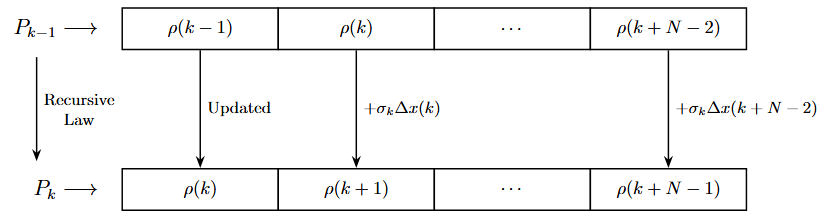

The code extract with the estimation loop and MPC computation is presented:

for k = 1:Sim_samples
    h1 = x_prev(1); h2 = x_prev(2);
    xf = xf + Ts*(-xf/tau+r(k)/tau);
    x_ref = [xf;xf];
    
    tic;
    % Estimate trajectory (TAYLOR RECURSIVE)
    Pk = compute_schedul_taylor_recursive(mpc, x_prev, n_rho, my_sched_fun, my_jacob_fun, rho_min, rho_max);
    
    % Build  matrices
    A_lpv = project_matrix(compute_A, Pk, n_rho, n);
    
    % Update and solve
    mpc = update_mpc_dynamics(mpc, A_lpv, [], []);
    [u_prev, mpc, iter] = mpc_solve(mpc, x_prev, u_prev, xf, x_ref, [], [], []);
    tk = toc;
    
    rf_dat(:,k) = xf; h1_dat(:,k) = h1; h2_dat(:,k) = h2; u_dat(k) = u_prev; t_dat(k) = tk;
    
    h1 = h1 + Ts*(u_prev/Ab-sqrt(2*g)*sqrt(h1)/Ab);
    h2 = h2 + Ts*(sqrt(2*g)*sqrt(h1)/Ab-sqrt(2*g)*sqrt(h2)/Ab);
    x_prev = [h1;h2];
end

## Results & Plots 

Finally, we plot the water height tracking performance, the control action (input mass flow) and its variation, along with the solver compute time per iteration. 

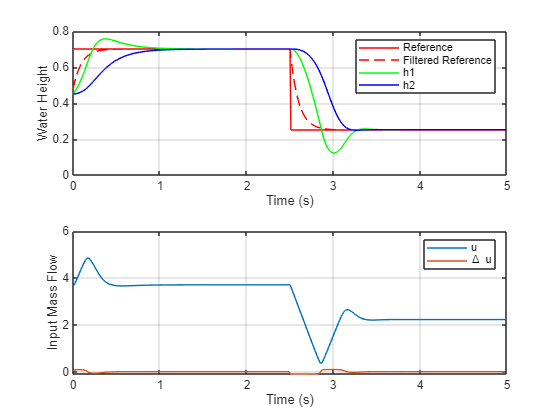

%% Plots
figure
ax1 = subplot(2,1,1);
plot(time,r,'r',time,rf_dat,'--r',time,h1_dat,'g',time,h2_dat,'b')
grid on
legend('Reference','Filtered Reference','h1','h2')
xlabel('Time (s)')
ylabel('Water Height')

ax2 = subplot(2,1,2);
plot(time,u_dat,time(1:end-1),diff(u_dat))
grid on
legend('u','\Delta u')
xlabel('Time (s)')
ylabel('Input Mass Flow')
linkaxes([ax1,ax2],'x')

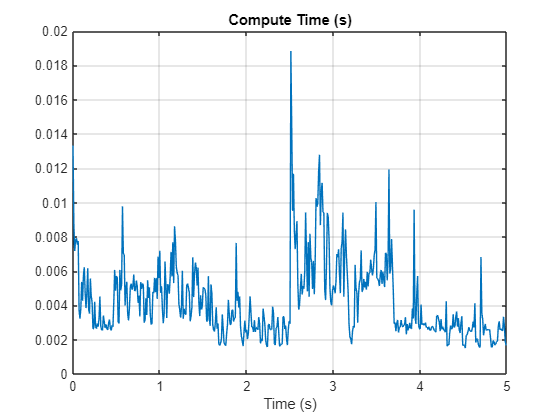


figure
plot(time,t_dat)
title('Compute Time (s)')
xlabel('Time (s)')
grid on